# **InverseJacobiCN**

[Inverse of the Jacobi elliptic function cn](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{cn}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\sqrt{1-x^2 }\left|m\right.\right) & m\le 1\\
\frac{{\textrm{dn}}^{-1} \left(x\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{cn}}^{-1} \left(x,k\right)\equiv {\mathrm{cn}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  Jacobi form of the elliptic integral of the first kind.

Domain:  If $-\infty <m\le 1$ then $-1\le x\le 1$ . If $m>1$ then $\left|x\right|<\sqrt{1-m^{-1} }$.  For the specified domain, the  codomain  is the set of real numbers.

Basic features:

Special values:

${\textrm{cn}}^{-1} \left(-1\left|m\right.\right)=2K\left(m\right)$,    ${\mathrm{cn}}^{-1} \left(0\left|m\right.\right)=K\left(m\right)$,    ${\textrm{cn}}^{-1} \left(1\left|m\right.\right)=0$

${\textrm{cn}}^{-1} \left(x\left|0\right.\right)={\mathrm{cos}}^{-1} x$,    ${\textrm{cn}}^{-1} \left(x\left|1\right.\right)={\mathrm{sech}}^{-1} x$

Identities:


$${\mathrm{cn}}^{-1} \left(\mathrm{cn}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{cn}\left({\textrm{cn}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x$$



$${\textrm{cn}}^{-1} \left(x\left|m\right.\right)=F\left(\cos^{-1} \;x\left|m\right.\right)$$


$K\left(m\right)$ is the complete elliptic integral of the first kind and $F\left(x\left|m\right.\right)$ is  Legendre form of the elliptic integral of the first kind.

## Syntax

Y = InverseJacobiCN(X,K)

y = ijcn(x,k)

Y = mInverseJacobiCN(X,M)

y = mijcn(x,m)

## Description

**Y = InverseJacobiCN(X,K)** return${\;\mathrm{cn}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the scne size or any of them can be scalar. **InverseJacobiCN** is the wrapper function which calls the functions **ijcn** element-wise via the function **ufun2**.

**y = ijcn(x,k)** return the value of ${\mathrm{cn}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijcn** is the wrapper function which calls the functions **mijcn**.

**Y = mInverseJacobiCN(X,M)** returns ${\mathrm{cn}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parcneter). X and M must be real and the scne size or any of them can be scalar. **mInverseJacobiCN** is the wrapper function which calls the functions **mijcn** element-wise via the function **ufun2**.

**y = mijcn(x,m)** compute value of ${\mathrm{cn}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parcneter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijcn **call the function **melF **for calculation of ${\mathrm{cn}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
[ijcn(x,k), InverseJacobiCN(x,k), mijcn(x,k^2), mInverseJacobiCN(x,k^2)]

ans =    1.089550670051885   1.089550670051885   1.089550670051885   1.089550670051885


% Maple 1.089550670051885_41


Accuracy.

fprintf('%.16g\n',mijcn(0.5,-4)) 

0.7663454616725307


%  Maple  .7663454616725306_64

Special values

m = -3; % m<1
disp(mijcn(-1,m)-2*melK(m))

     0



disp(mijcn(0,m) - melK(m))  % m < 1 !!!

     0



mijcn(1,m)

ans = 0

x=0.5;
disp(mijcn(x,0) - acos(x)) 

     0



disp(mijcn(x,1) - asech(x))

     0



Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mJacobiCN(mInverseJacobiCN(x,m),m)-x)

     0



disp(mInverseJacobiCN(x,m) - mpEllipticF(acos(x),m))

     0



k = 0.99995;
x = 0.9999*elK(k);
disp(InverseJacobiCN(JacobiCN(x,k),k)-x)

     3.389999392311438e-11



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
x = -0.2;
disp(mInverseJacobiCN(x,m) - mpEllipticF(acos(x),m))

   1.0e-14 *

                   0   0.044408920985006                   0   0.177635683940025



**Matrix input**

M = [0.1, 0.5, 0.89; -1, -97, 0.99995 ]';
x = -0.4;
disp(mInverseJacobiCN(x,M) - mpEllipticF(acos(x),M))

   1.0e-15 *

  -0.444089209850063  -0.222044604925031
                   0  -0.055511151231258
  -0.444089209850063                   0



## **Plot **

**Example 1**

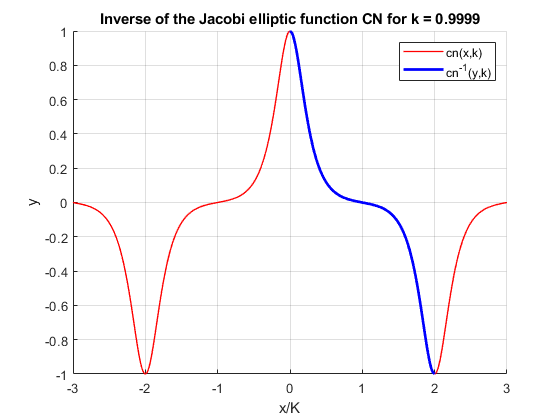

figure
hold on
x=-3:0.01:3;
k = 0.9999;
M = elK(k);
plot(x,JacobiCN(M*x,k),'LineWidth',1.0,'Color','red')
x=-1:0.01:1;
plot(InverseJacobiCN(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('cn(x,k)','cn^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Inverse of the Jacobi elliptic function CN for k = %g',k))
grid on
hold off

**Example 2**

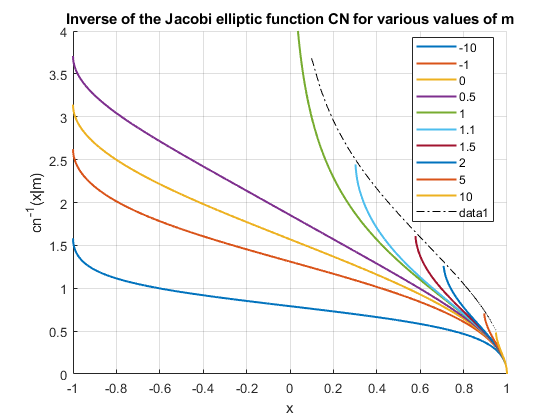

figure
hold on
X = -1:0.001:1;
M = [-10,-1,0,0.5,1,1.1,1.5,2,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiCN(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) 0 4])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function CN for various values of m')
N=1:0.01:10;
X = sqrt(1-1./N);
plot(X,mInverseJacobiCN(X,N),'k-.')
xlabel('x')
ylabel('cn^{-1}(x|m)')

**Example 3**

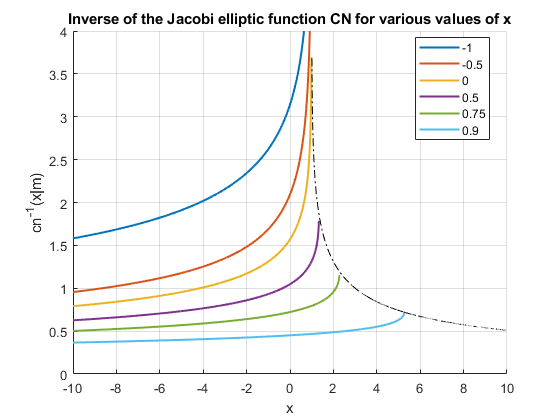

figure
hold on
M = -10:0.01:10;
X = [-1,-0.5,0,0.5,0.75,0.9];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiCN(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
%axis([min(M) max(M) -3 3])
ylim([0  4])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function CN for various values of x')
xlabel('x')
ylabel('cn^{-1}(x|m)')
M = 1:0.01:10;
F = mInverseJacobiCN(sqrt(1-1./M),M);
plot(M,F,'k-.')
%plot(M,-F)
hold off

**Example 4**

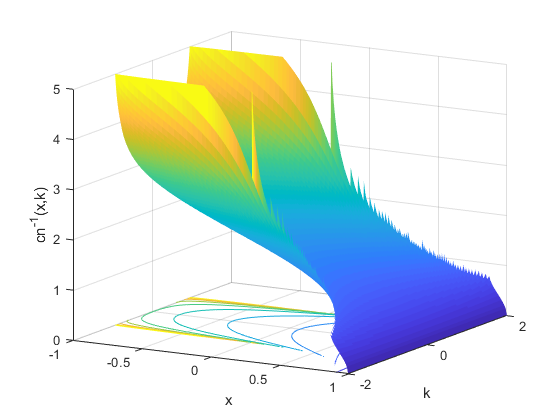

figure
x=-1:0.01:1;
k=-2:0.01:2;
zz = 5;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiCN(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view([30 15])
caxis([0 zz])
xlabel('x')
ylabel('k')
zlabel('cn^{-1}(x,k)')
zlim([0 zz])
grid on

**Example 4**

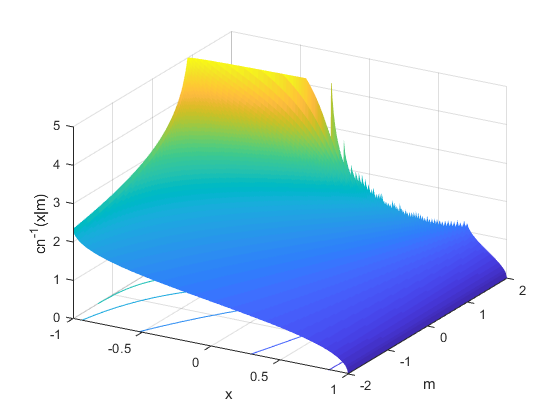

figure
x=-1:0.01:1;
m=-2:0.01:2;
zz = 5;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiCN(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view([30 30])
caxis([0 zz])
xlabel('x')
ylabel('m')
zlabel('cn^{-1}(x|m)')
zlim([0 zz])
grid on

**Example 5**

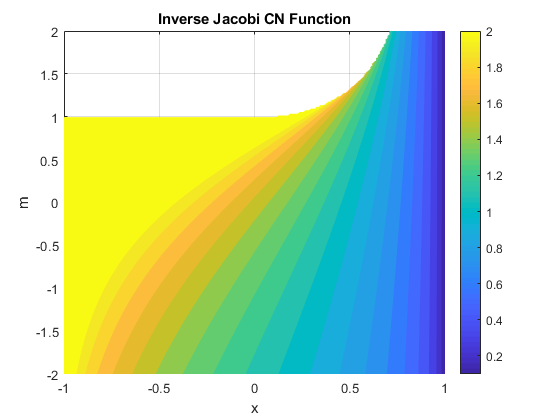

figure
f = @(x,m)mInverseJacobiCN(x,m);
fcontour(f,[-1 1 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi CN Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 6**

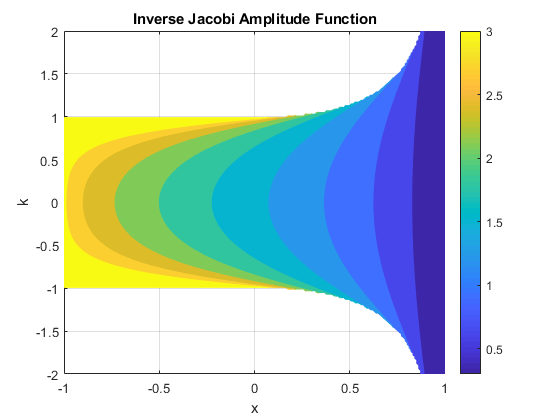

figure
f = @(x,k)InverseJacobiCN(x,k);
fcontour(f,[-1 1 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi Amplitude Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also